# Load file

y -- Actual data sequence Fs -- Stated frequency of sampling NN -- number of data points

clear all;

Fs = 8000; Channels = 1; bits = 8;
r = audiorecorder(Fs, bits, Channels);
duration = 5; disp('Started');

Started


recordblocking(r, duration);
disp("Stopped");

Stopped


X = getaudiodata(r);

sound(X, Fs, bits);

FileC = 'FileC.wav';
audiowrite(FileC, X, Fs);

[y,Fs] = audioread('FileA.wav');
sound(y,Fs)
pause(5.5);
[y,Fs] = audioread('FileB.wav');
sound(y,Fs)
pause(5.5);
[y,Fs] = audioread('FileC.wav');
sound(y,Fs)

[y,Fs] = audioread('FileC.wav');
sound(y,Fs)
NN=length(y);

## Plot data

For reference and visualization tt -- time variable= data index * Fs;

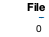

tt=(0:(NN-1))*Fs;
soundData=figure('Name', 'Sound data');
plot(tt, y);
xlabel('Time'); ylabel('Pressure');
title('File C');

## Fourier Transform

The fft gives a sequence 0:(N-1). Uses function fft- discrete Fourier transform Uses function fftshift - The FT is periodic. This shifts the FT from 0-N-1 to -(N-1)/2:(N-1)/2 if N odd or to -N/2:(N-1)/2 if N even. fS space of frequencies. The highest frequency is Fs and corresponds to the index N in spectral space. fS runs from 0 to Fs(NN-1)/N; fSH space of shifted frequencies corresponding to fftshift.

myFFT --Fourier transform of sample. myFFTH --Shifted Fourier transform of sample. myFFTR --Real part of Fourier transform of sample. myFFTI --Imaginary part of Fourier transform of sample.

myFFT=fft(y);
myFFTR=real(myFFT); %Real Components
myFFTI=imag(myFFT); %Imaginary Components

myFFTH=fftshift(myFFT); 
myFFTHR=real(myFFTH);  %Real Shifted Components
myFFTHI=imag(myFFTH);  %Imaginary Shifted Components

fS=(0:(NN-1))*Fs/NN;

if  rem(NN,2)==1  % Is NN odd?
    fSH=(-(NN-1)/2):((NN-1)/2);
    fSH=fSH*Fs/NN; %sets the scale
else
    fSH=((-NN/2):((NN-1)/2));
    fSH=fSH*Fs/NN; %sets the scale
end

## Plots of transform no shift

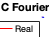

figure;
hold on;
plot(fS, myFFTR, 'r');
plot(fS, myFFTI, 'b');
xlabel('Frequency');
ylabel('Pressure Coeff');
title('File C Fourier Coeffients');
xlim([0 1500]);
legend('Real', 'Imag');
hold off;

## Plots of transform with shift

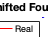

figure;
hold on;
plot(fSH, myFFTHR, 'r');
plot(fSH, myFFTHI, 'b');
xlabel('Frequency');
ylabel('Pressure Coeff');
title('File C Shifted Fourier Coeffcients');
xlim([-1500 1500]);
legend('Real', 'Imag');
hold off;

## Filter A High

High pass. Kill all the componets at high frequency To recreate the pressure wave we do inverse tranform. yA pressure wave cA Cutoff in Hertz

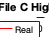

cA=3000;
indA=(abs(fSH)>cA);
myFFTAH=zeros(NN,1); % Set zero everyhwere
myFFTAH(indA)=myFFTH(indA); % Copy only in the region selected
myFFTAHR=real(myFFTAH);
myFFTAHI=imag(myFFTAH);
myFFTA=ifftshift(myFFTAH); % inverseShift
myFFTAR=real(myFFTA);
myFFTAI=real(myFFTA);

figure;
plot(fSH, myFFTAHR, 'r');
hold on;
plot(fSH, myFFTAHI, 'b');
xlabel('Frequency');
ylabel('Pressure Coeff');
title('File C High Pass');
xlim([-3500 3500]);
legend('Real', 'Imag');
hold off;

yA=real(ifft(myFFTA));

%yA = yA * 1.3;

FileCHigh = 'FileCHigh.wav';
audiowrite('FileCHigh.wav',yA,Fs);

[y,Fs] = audioread('FileC.wav');
sound(y,Fs)
pause(5.5);
[y,Fs] = audioread('FileCHigh.wav');
sound(y,Fs)

## Flter B Low

Low pass. Kill all the componets at low frequency To recreate the pressure wave we do inverse tranform. yB pressure wave

## cB Cutoff in Hertz

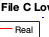

cB=950;
indB=(abs(fSH)<cB);
myFFTBH=zeros(NN,1); % Set zero everyhwere
myFFTBH(indB)=myFFTH(indB); % Copy only in the region selected
myFFTBHR=real(myFFTBH);
myFFTBHI=imag(myFFTBH);
myFFTB=ifftshift(myFFTBH); % inverseShift
myFFTBR=real(myFFTB);
myFFTBI=real(myFFTB);

figure;
plot(fSH, myFFTBHR, 'r');
hold on;
plot(fSH, myFFTBHI, 'b');
legend('Real', 'Imag');
xlabel('Frequency');
ylabel('Pressure Coeff');
title('File C Low Pass');
xlim([-3500 3500]); 
hold off;

yB=real(ifft(myFFTB));
yB = yB * 5 + 0.3;

FileCLowAlt = 'FileCLowAlt.wav'

FileCLowAlt = 'FileCLowAlt.wav'

audiowrite('FileCLowAlt.wav',yB,Fs);

[y,Fs] = audioread('FileC.wav');
sound(y,Fs)
pause(5.5);
[y,Fs] = audioread('FileCLowAlt.wav');
sound(y,Fs)

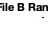

cC = 2600;
cC2 = 3400;

indC = (abs(fSH) > cC2) | (abs(fSH) < cC);

myFFTCH=zeros(NN,1); % Set zero everyhwere
myFFTCH(indC)=myFFTH(indC); % Copy only in the region selected
myFFTCHR=real(myFFTCH);
myFFTCHI=imag(myFFTCH);
myFFTC=ifftshift(myFFTCH); % inverseShift
myFFTCR=real(myFFTC);
myFFTCI=real(myFFTC);

figure;
plot(fSH, myFFTCHR, 'r');
hold on;
plot(fSH, myFFTCHI, 'b');
xlabel('Frequency');
ylabel('Pressure Coeff');
title('File B Range Pass');
xlim([-3500 3500]);
hold off;

yC=real(ifft(myFFTC));

FileCRange = 'FileCRange'

FileBRange = 'FileBRange'

audiowrite('FileCRange.wav',yC,Fs);

[y,Fs] = audioread('FileC.wav');
sound(y,Fs)
pause(5.5);
[y,Fs] = audioread('FileCRange.wav');
sound(y,Fs)